# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.6 特殊绘图

#### 2.6.19 卫星从低轨道变到低轨道

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

clear;clc;
tic;
mu = 398600; % 地球引力常数
R = 6371;    % 地球半径
H = 400;     % 卫星高度
angle = 51/180*pi;  % 卫星轨道倾角
T2 = 23*3600 + 56*60 + 4; % 地球同步轨道周期
m = 6400; % 假设卫星总质量为6.4吨
P = 160;  % 发动机采用160kN小型轨控发动机
ap = P/m; % 轨控发动机所能提供的整星加速度，不考虑卫星质量变化和推力变化

a1 = R + H;  % 卫星轨道半径
v1 = sqrt(mu/a1);  % 卫星初始速度
T1 = 2*pi*sqrt(a1^3/mu);  % 卫星轨道周期
% a2 = (T2^2*mu/4/pi^2)^(1/3);  % 地球同步轨道半径
a2 = R + 2000;
v2 = sqrt(mu/a2);  % 地球同步轨道速度
ad = (a1 + a2)/2;  % 转移轨道半长轴
e = (a2 - a1)/(a2 + a1);  % 转移轨道偏心率
va = sqrt(mu/(ad*(1 - e^2)))*(1 - e);  % 转移轨道远地点速度
vp = sqrt(mu/(ad*(1 - e^2)))*(1 + e);  % 转移轨道近地点速度
vd = (vp - v1) + (v2 - va);  % 速度增量
td = pi*sqrt(ad^3/mu);  % 转移时间
t1 = (vp - v1)/ap;  % 第一次发动机运行时间
t2 = (v2 - va)/ap;  % 第二次发动机运行时间

T = 196917;       % 计算总时间
ti = 0.5;         % 计算时间间隔
n = T/ti + 5500;  % 计算总次数
t1k = (T1 - t1/2)/ti;  % 第一次发动机开机时间位置
t1g = (T1 + t1/2)/ti;  % 第一次发动机关机时间位置
t2k = floor((T1 + td - t2/2)/ti);  % 第二次发动机开机时间位置
t2g = (T1 + td + t2/2)/ti;  % 第二次发动机关机时间位置

% 设置时间，可以控制卫星环绕圈数
t3k = floor((T1 + td + T2)/ti);  

r0 = [a1 0 0];  % 卫星位置坐标
v0 = [0 v1*cos(angle) v1*sin(angle)];  % 卫星速度矢量
a0= -mu/(norm(r0)^3)*r0;   % 卫星加速度矢量
h0 = [0 0 0];  % 卫星角动量
rp0 = norm(r0);  % 卫星实时地心距
cs0 = 0;  % 推力开关
th = 5000;  % 绘图时间间隔

%%% 计算所有的结果
% 初始化
N = t3k;
t = zeros(N, 1);
r = zeros(N, 3);
cs = zeros(N, 1);
rp = zeros(N, 1);
v = zeros(N, 3);
a = zeros(N, 3);
h = zeros(N, 3);
t(1) = ti;
r(1, :) = r0;
v(1, :) = v0;
a(1, :) = a0;
h(1, :) = h0;
rp(1) = rp0;
cs(1) = cs0;

for j = 2:N
    t(j) = t(j-1) + ti;
    r(j, :) = r(j-1, :) + v(j-1, :)*ti;
    v(j, :) = v(j-1, :) + a(j-1, :)*ti;
    rp(j) = norm(r(j, :));
    
    % 计算推力开关
    if (j > t1k && j < t1g) || (j > t2k && j < t2g)
        cs(j) = 1;
    end

    a(j, :) = -mu/(rp(j)^3)*r(j, :) + ap*cs(j)/norm(v(j, :))*v(j, :);
end

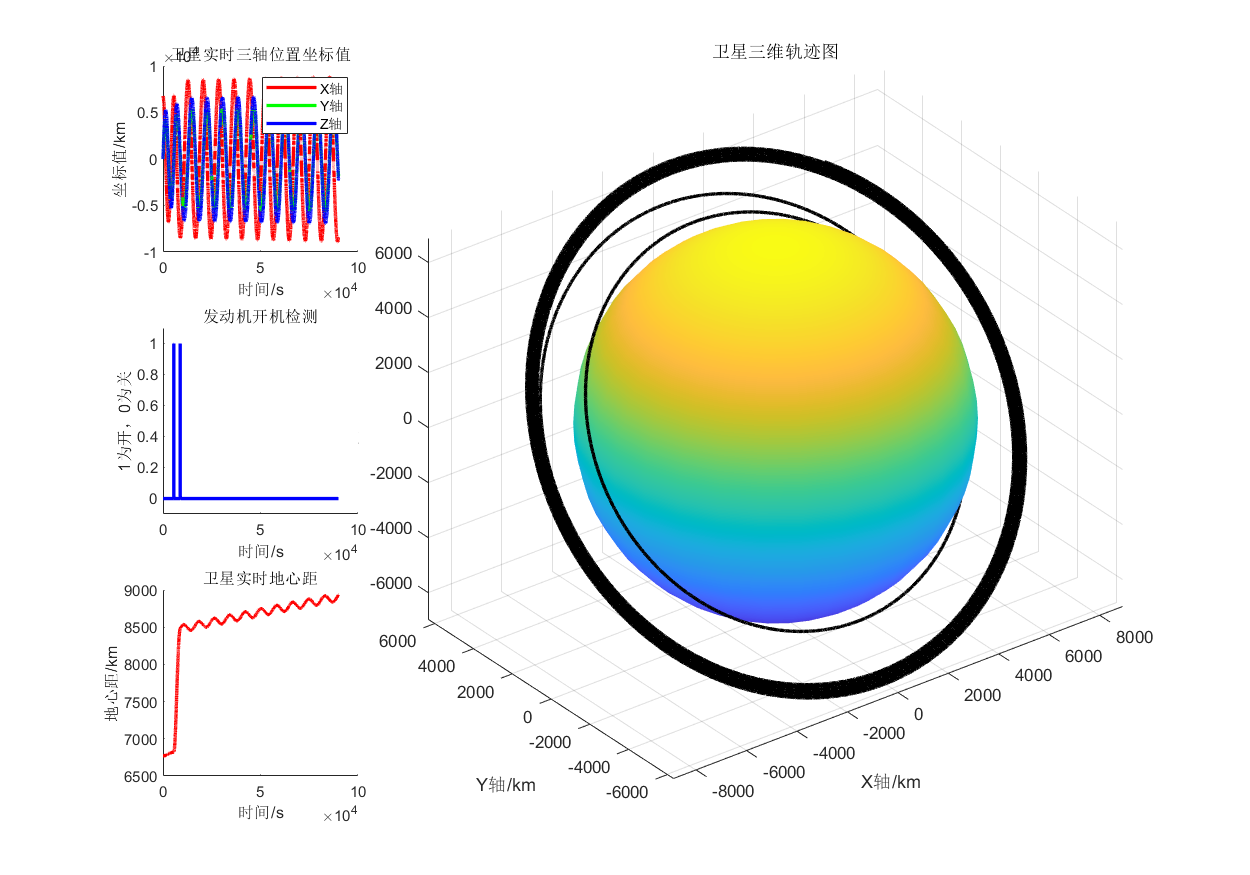

%%% 绘图 数据量过大，每次绘制一段
close;
figure('Position', [50, 50, 1000, 700]);
subplot(3, 4, [2:4, 6:8, 10:12])
[x, y, z] = sphere(30);  % 设置经纬分面数
x = R*x;
y = R*y;
z = R*z;
surf(x, y, z)
axis equal
shading interp

l = floor(th/ti);
for j = 1:N
    pos = floor(j/th*ti); 
   if abs(pos - j/th*ti) < 1e-6
       subplot(3, 4, 1)
       hold on
       plot(t((pos-1)*l+1:pos*l), r((pos-1)*l+1:pos*l, 1), 'r', 'LineWidth', 2);
       plot(t((pos-1)*l+1:pos*l), r((pos-1)*l+1:pos*l, 2), 'g', 'LineWidth', 2);
       plot(t((pos-1)*l+1:pos*l), r((pos-1)*l+1:pos*l, 3), 'b', 'LineWidth', 2);
       title('卫星实时三轴位置坐标值');
       xlabel('时间/s');
       ylabel('坐标值/km');
       legend('X轴', 'Y轴', 'Z轴');
       
       subplot(3, 4, 5)
       hold on
       plot(t((pos-1)*l+1:pos*l), cs((pos-1)*l+1:pos*l), 'b', 'LineWidth', 2);
       title('发动机开机检测');
       xlabel('时间/s');
       ylabel('1为开，0为关');
       ylim([-0.1 1.1]);
       
       subplot(3, 4, 9)
       hold on
       plot(t((pos-1)*l+1:pos*l), rp((pos-1)*l+1:pos*l), 'r', 'LineWidth', 2);
       title('卫星实时地心距');
       xlabel('时间/s');
       ylabel('地心距/km');
       
       subplot(3, 4, [2:4, 6:8, 10:12])
       hold on
       plot3(r((pos-1)*l+1:pos*l, 1), r((pos-1)*l+1:pos*l, 2), r((pos-1)*l+1:pos*l, 3), 'k', 'LineWidth', 2);
       title('卫星三维轨迹图');
       xlabel('X轴/km');
       ylabel('Y轴/km');
       zlabel('Z轴/km');
       pause(0.01);
   end
end
subplot(3, 4, [2:4, 6:8, 10:12])
plot3(r(pos*l:end, 1), r(pos*l:end, 2), r(pos*l:end, 3), 'k', 'LineWidth', 2);

toc;

历时 10.083172 秒。
